# Metody optymalizacji - moduł 5

# Zadanie 1

### Nina Łabęcka 311339 grupa czwartek 14:15

### Dominika Pacek 311378 grupa czwartek 18:15

clc
clear

Definicje funkcji i ich pochodnych

fun1 = @(x) 20*x.^2 - 44*x + 29;
fun1p = @(x) 40*x - 44;
fun2 = @(x) 40*x.^3 + fun1(x);
fun2p = @(x) 120*x.^2 + fun1p(x);

Parametry

alfa = 0.3;
beta = 0.9;
start = 1;

Rysunek funkcji 20*x.^2 - 44*x + 29

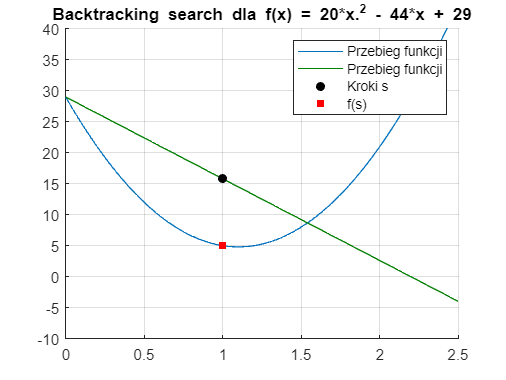

figure;
hold on
grid on
l = @(x, a) fun1(0) + a * fun1p(0) * x;
X = linspace(0, 2.5, 100);

do_and_draw_backtrack_search(0, 2.5, fun1, fun1p, alfa, beta, start, [0 2.5 -10 40])
title('Backtracking search dla f(x) = 20*x.^2 - 44*x + 29');
legend()

Parametry

alfa = 0.4;
beta = 0.9;
start = 1;

Rysunek funkcji 40*x.^3 + 20*x.^2 - 44*x + 29

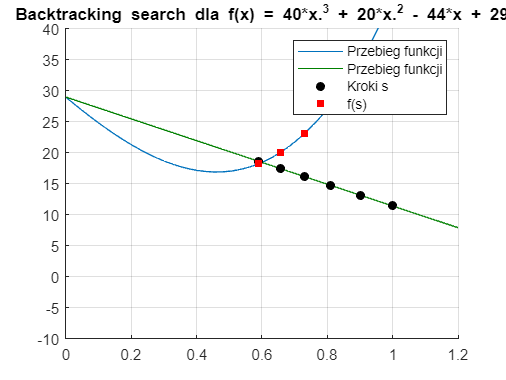

figure;
hold on
grid on
l = @(x, a) fun2(0) + a * fun2p(0) * x;
X = linspace(0, 2.5, 100);

do_and_draw_backtrack_search(0, 2.5, fun2, fun2p, alfa, beta, start, [0 1.2 -10 40])
title('Backtracking search dla f(x) = 40*x.^3 + 20*x.^2 - 44*x + 29');
legend()

function [s, history] = backtracking_search(fun, funp, alfa, beta, start)
    s = start;
    history = s;
    while fun(s) >= fun(0) + alfa * funp(0)*s
        s = beta * s;
        history = [history s];
    end
end

function do_and_draw_backtrack_search(x_min, x_max, fun, funp, alfa, beta, start, ...
    graph_limits)

X = linspace(x_min, x_max, 100);

plot(X, fun(X), 'DisplayName', 'Przebieg funkcji');
[~, history] = backtracking_search(fun, funp, alfa, beta, start);

l = @(x, a) fun(0) + a * funp(0) * x;
plot(X, l(X, alfa), 'Color', [0 0.5 0], 'DisplayName', 'Przebieg funkcji');
scatter(history, l(history, alfa), 'MarkerEdgeColor', 'none', 'MarkerFaceColor', 'black', ...
    'DisplayName', 'Kroki s');
scatter(history, fun(history), 's', 'filled', 'MarkerFaceColor', 'red', 'DisplayName', 'f(s)');

axis(graph_limits);

end